# Post Calculations of Ising

## Constants

T_crit_theo=2/log(1+sqrt(2))

T_crit_theo = 2.2692

## Import data to multidim array

[N_vals,T_vals,data] = importMulti('IsingResultsNew4.tsv');
%remove N=256
data(end,:,:,:)=[];
N_vals(end)=[];
T_vals(:,end)=[];

## Reweight magnetization

for i=2.2727:0.001:2.35484
    for j=4:4
        [N_vals,T_vals,data] = addReweightToData(N_vals,T_vals,data,i,j);
    end
end

%clean outliners
T_vals([40,42],:)=[];
data(:,[40,42],:,:)=[];

% sort new temps again ascending
sampleIndex=0
[T_vals(:,sampleNindex),I]=sort(T_vals(:,sampleNindex));
data(sampleNindex,:,:,:)=data(sampleNindex,I,:,:);

## Reduce data to mean and std

[O_mean,O_std,O_var,O_var_err,O_weight,O_corrLength] = ReduceObservableMulti(data);

## Plot energy

figure('Position',[10 10 1200 900])
clf
subplot(2,2,1)
for i=1:size(data,1)
    %errorbar(T_vals(:,i),reshape(O_mean(i,:,1,:),[],1), ...
    %    reshape(O_std(i,:,1,:),[],1),'DisplayName',"N="+N_vals(i))
    plot(T_vals(:,i),reshape(O_mean(i,:,1,:),[],1),'.','DisplayName',"N="+N_vals(i)+"^2",'MarkerSize',10)
    hold on
end
grid on
grid minor
box on
xlabel("temperature T")
ylabel("normalized energy E")
legend("Location","best")
title("energy E")
%saveas(gcf,'./plots/measuredAndRewEnergy.png');

## Plot magnetization

subplot(2,2,2)
for i=1:size(data,1)
    %errorbar(T_vals(:,i),reshape(O_mean(i,:,2,:),[],1), ...
    %    reshape(O_std(i,:,2,:),[],1),'DisplayName',"N="+N_vals(i))
    plot(T_vals(:,i),reshape(O_mean(i,:,2,:),[],1),'.','DisplayName',"N="+N_vals(i)+"^2",'MarkerSize',10)
    hold on
end
grid on
grid minor
box on
xlabel("temperature T")
ylabel("absolute magnetization M")
legend("Location","best")
title("magnetization M")
%saveas(gcf,'./plots/measuredAndRewMagnet.png');

## heat capacity

heatCap=reshape(O_var(:,:,1),length(N_vals),[])'.*N_vals.^2./T_vals.^2;
heatCap_err=reshape(O_var_err(:,:,1),length(N_vals),[])'.*N_vals.^2./T_vals.^2;

subplot(2,2,3)
for i=1:size(data,1)
    if i==4
        plot(T_vals(1:end-80,i),heatCap(1:end-80,i),'.','DisplayName',"N="+N_vals(i)+"^2",'MarkerSize',10)
    else
        plot(T_vals(:,i),heatCap(:,i),'.','DisplayName',"N="+N_vals(i)+"^2",'MarkerSize',10)
    end

    hold on
end
grid on
grid minor
box on
xlabel("temperature T")
ylabel("heat capacity C")
legend("Location","best")
title("heat capacity C")

## susceptibility

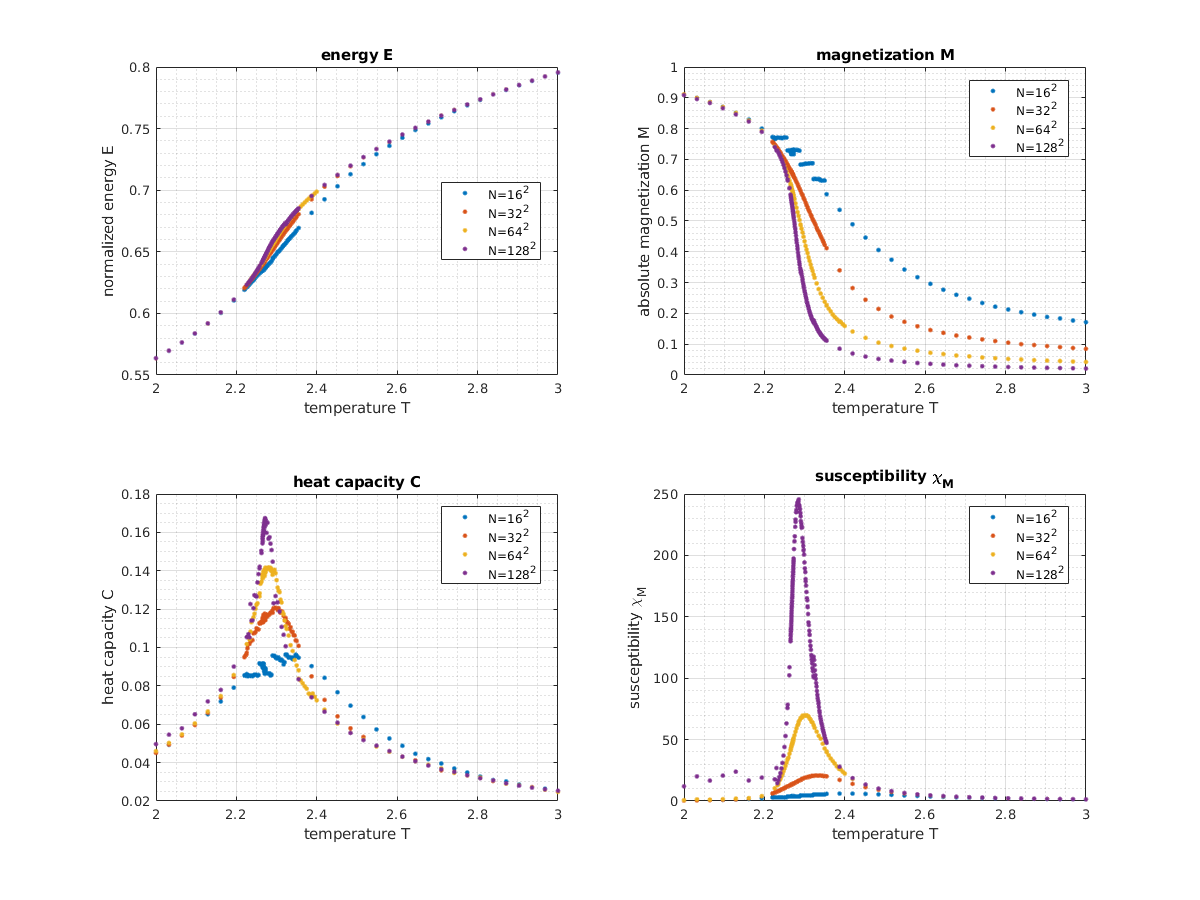

suscept=reshape(O_var(:,:,2),length(N_vals),[])'./T_vals.*N_vals.^2;
suscept_err=reshape(O_var_err(:,:,2),length(N_vals),[])'./T_vals.*N_vals.^2;

subplot(2,2,4)
for i=1:size(data,1)
    plot(T_vals(:,i),suscept(:,i),'.','DisplayName',"N="+N_vals(i)+"^2",'MarkerSize',10)
    hold on
end
grid on
grid minor
box on
xlabel("temperature T")
ylabel("susceptibility \chi_M")
legend("Location","best")
title("susceptibility \chi_M")
saveas(gcf,'./plots/measuredAndRewObservables.png');

## Fit magnetization

figure('Position', [10 10 1200 900])
clf
for i=1:size(data,1)
    [t_cleaned,y_cleaned]=prepareCurveData(T_vals(:,i), reshape(O_mean(i,:,2,:),[],1).*N_vals(i).^2);
    if(i==1)
        [t_cleaned,y_cleaned]=prepareCurveData(T_vals(1:32,i), reshape(O_mean(i,1:32,2,:),[],1).*N_vals(i).^2);
    end
    x=[2:0.01:3 ]';
    [t_cleaned,ia]=unique(t_cleaned);
    y=interp1(t_cleaned,y_cleaned(ia),x,"linear");

    ft = fittype( 'a*abs(T-Tc)^beta+1', 'independent', 'T', 'dependent', 'y' );
    excludedPoints = y < N_vals(i).^2 /2;
    opts = fitoptions( 'Method', 'NonlinearLeastSquares' );
    opts.Display = 'Off';
    opts.Lower = [2 -Inf -Inf];
    opts.StartPoint = [3 N_vals(i).^2 0.8];
    opts.Upper = [5 Inf 1];
    opts.Exclude = excludedPoints;
    [fitM_exponent, gof_M_exponent] = fit( x, y, ft, opts )


    T_c_N(i)=fitM_exponent.Tc;
    beta_N(i)=fitM_exponent.beta;

    subplot(2,2,i)
    p=plot( fitM_exponent, x,y,excludedPoints);
    p(1).MarkerSize=10;
    grid on
    box on
    xlabel("temperature T")
    ylabel("magnetization M")
    title("magnetization N="+N_vals(i)+"^2, T_c="+fitM_exponent.Tc)
    legend("Location","east")
end

fitM_exponent =      General model:
     fitM_exponent(T) = a*abs(T-Tc)^beta+1
     Coefficients (with 95% confidence bounds):
       Tc =       2.464  (2.449, 2.478)
       a =       299.8  (294.5, 305.2)
       beta =      0.3059  (0.2794, 0.3323)

gof_M_exponent = struct with fields:
           sse: 247.1182
       rsquare: 0.9943
           dfe: 39
    adjrsquare: 0.9940
          rmse: 2.5172


fitM_exponent =      General model:
     fitM_exponent(T) = a*abs(T-Tc)^beta+1
     Coefficients (with 95% confidence bounds):
       Tc =       2.333  (2.328, 2.338)
       a =        1182  (1156, 1208)
       beta =      0.1993  (0.1834, 0.2151)

gof_M_exponent = struct with fields:
           sse: 4.1357e+03
       rsquare: 0.9911
           dfe: 30
    adjrsquare: 0.9905
          rmse: 11.7412


fitM_exponent =      General model:
     fitM_exponent(T) = a*abs(T-Tc)^beta+1
     Coefficients (with 95% confidence bounds):
       Tc =       2.286  (2.284, 2.288)
       a =        4495  (4435, 4556)
       beta =      0.1412  (0.1334, 0.1489)

gof_M_exponent = struct with fields:
           sse: 2.3482e+04
       rsquare: 0.9948
           dfe: 26
    adjrsquare: 0.9944
          rmse: 30.0526


fitM_exponent =      General model:
     fitM_exponent(T) = a*abs(T-Tc)^beta+1
     Coefficients (with 95% confidence bounds):
       Tc =       2.274  (2.273, 2.274)
       a =   1.752e+04  (1.74e+04, 1.763e+04)
       beta =      0.1222  (0.1188, 0.1257)

gof_M_exponent = struct with fields:
           sse: 9.5969e+04
       rsquare: 0.9984
           dfe: 25
    adjrsquare: 0.9983
          rmse: 61.9577


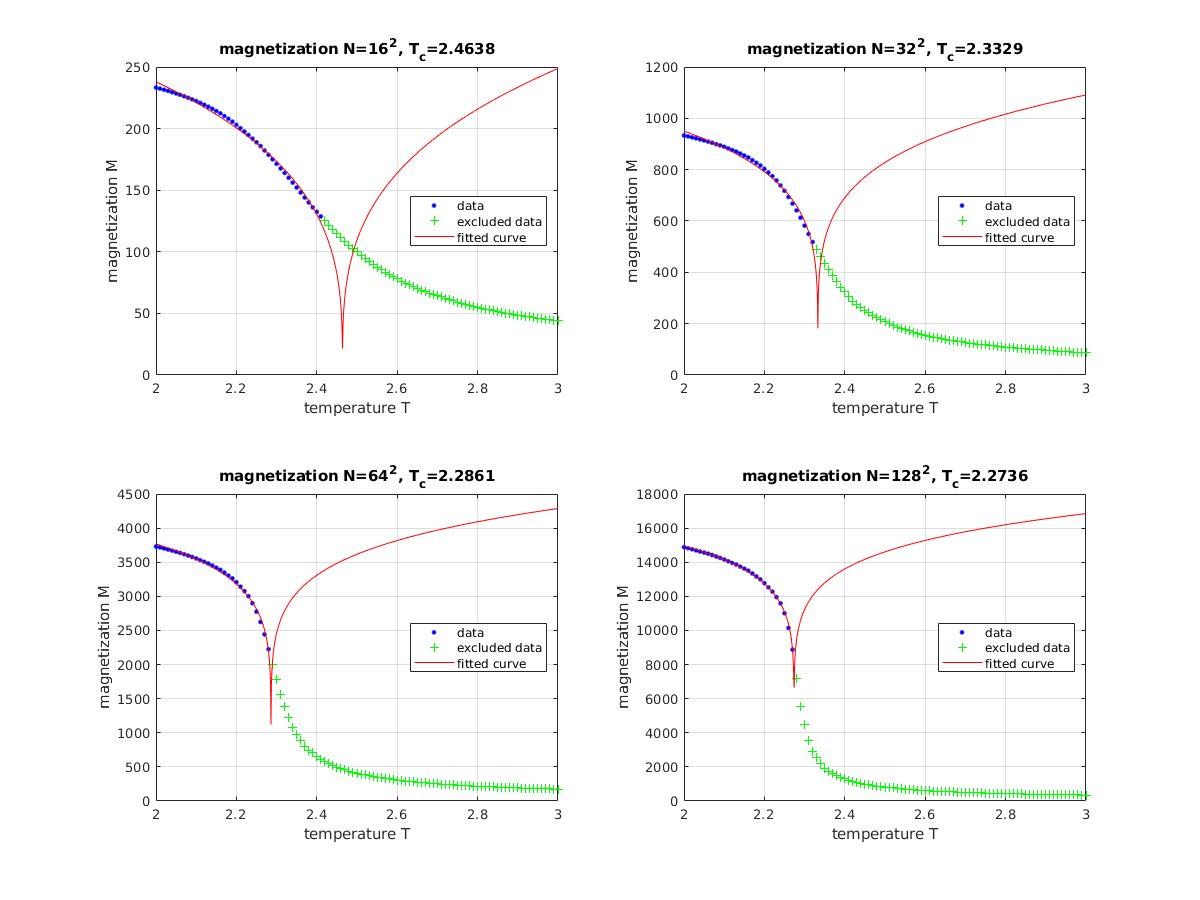

saveas(gcf,'./plots/measuredAndRewMagnet_fit.png');

# Fit critical exponents

figure('Position', [10 10 1200 900])
clf
subplot(2,2,4)

## critical T for finite size systems

T_c_N

T_c_N =     2.4638    2.3329    2.2861    2.2736


T_c_N_err=abs(T_c_N-T_crit_theo);

ft = fittype( 'poly1' );
opts = fitoptions( 'Method', 'NonlinearLeastSquares' );
opts.Display = 'Off';
opts.Lower = [-Inf 0.4];
opts.StartPoint = [0 1];
opts.Upper = [Inf 1.2];

% Fit model to data.
[fitMagnetTcrit,~] = fit( log(N_vals.^2)',log(T_c_N_err)', ft)

fitMagnetTcrit =      Linear model Poly1:
     fitMagnetTcrit(x) = p1*x + p2
     Coefficients (with 95% confidence bounds):
       p1 =     -0.9131  (-1.028, -0.7983)
       p2 =       3.491  (2.598, 4.383)

p1=fitMagnetTcrit.p1*-1;
nu_err=round(table(diff(confint(fitMagnetTcrit))/2).Var1(1)/p1.^2,3);

plot(fitMagnetTcrit,log(N_vals.^2),log(T_c_N_err))
title("finite size scale error of T_c: \nu="+round(1/p1,3)+"+-"+nu_err)
xlabel("log Number of spins N")
ylabel("log |T_c-T_c(N)|")
grid on
%saveas(gcf,'./plots/Tcrit_err_N_nu.png')

## beta for finite size systems

subplot(2,2,2)
ft = fittype( 'poly1' );

% Fit model to data.
x=log(N_vals(1:end).^2)';
y=log(abs(beta_N(1:end)))';
[fitbeta,~] = fit( x,y, ft )

fitbeta =      Linear model Poly1:
     fitbeta(x) = p1*x + p2
     Coefficients (with 95% confidence bounds):
       p1 =     -0.2233  (-0.3652, -0.08143)
       p2 =    -0.01149  (-1.116, 1.093)


beta=fitbeta.p1*-1;
beta_err=round(table(diff(confint(fitbeta))/2).Var1(1),3);

plot(fitbeta,x,y)
title("finite size scale beta: \beta="+round(beta,3)+"+-"+beta_err)
xlabel("log Number of spins N")
ylabel("log \beta(N)")
grid on
%saveas(gcf,'./plots/magnet_beta.png')

## heat cap: alpha

Analyse now maxima in log-log-plot and fit a linear equation to the data

subplot(2,2,1)

ft = fittype( 'poly1' );

% Fit model to data.
x=log(N_vals.^2)';
y=log(max(heatCap,[],1))';
[fitHeatCapMax, gof_hcm] = fit( x, y, ft )

fitHeatCapMax =      Linear model Poly1:
     fitHeatCapMax(x) = p1*x + p2
     Coefficients (with 95% confidence bounds):
       p1 =      0.1311  (0.0987, 0.1635)
       p2 =      -3.048  (-3.3, -2.796)

gof_hcm = struct with fields:
           sse: 0.0011
       rsquare: 0.9934
           dfe: 2
    adjrsquare: 0.9902
          rmse: 0.0234


plot(fitHeatCapMax,x,y)

hcap_p1=round(fitHeatCapMax.p1,2);
hcap_p1_err=round(table(diff(confint(fitHeatCapMax))/2).Var1(1),2);

grid on
box on
xlabel("log Number of spins N")
ylabel("maximum heat capacity C")
title("heat capacity maxima: \alpha="+hcap_p1+"+-"+hcap_p1_err)
legend("Location","best")
%saveas(gcf,'./plots/heatCapMax_alpha.png')

## Susceptibility: gamma

Analyse now maxima in log-log-plot and fit a linear equation to the data

subplot(2,2,3)
ft = fittype( 'poly1' );

% Fit model to data.
[x,y]=prepareCurveData(log(N_vals), log(max(suscept,[],1)));
[fitSusceptMax, gof_susc] = fit( x,y, ft )

fitSusceptMax =      Linear model Poly1:
     fitSusceptMax(x) = p1*x + p2
     Coefficients (with 95% confidence bounds):
       p1 =       1.777  (1.739, 1.815)
       p2 =      -3.127  (-3.274, -2.98)

gof_susc = struct with fields:
           sse: 3.7176e-04
       rsquare: 1.0000
           dfe: 2
    adjrsquare: 0.9999
          rmse: 0.0136


plot(fitSusceptMax,x,y)
%loglog(N_vals,max(suscept,[],1),'b.','DisplayName',"Data",'MarkerSize',10)
%hold on
%x=linspace(log(N_vals(1))-1,log(N_vals(end)),100);
%loglog(exp(x),exp(fitSusceptMax(x)),'-r','DisplayName',"Fit linear model")

Critical exponent

fitSusceptMax.p1

ans = 1.7770

suscept_p1_err=round(table(diff(confint(fitSusceptMax))/2).Var1(1),3)

suscept_p1_err = 0.0380

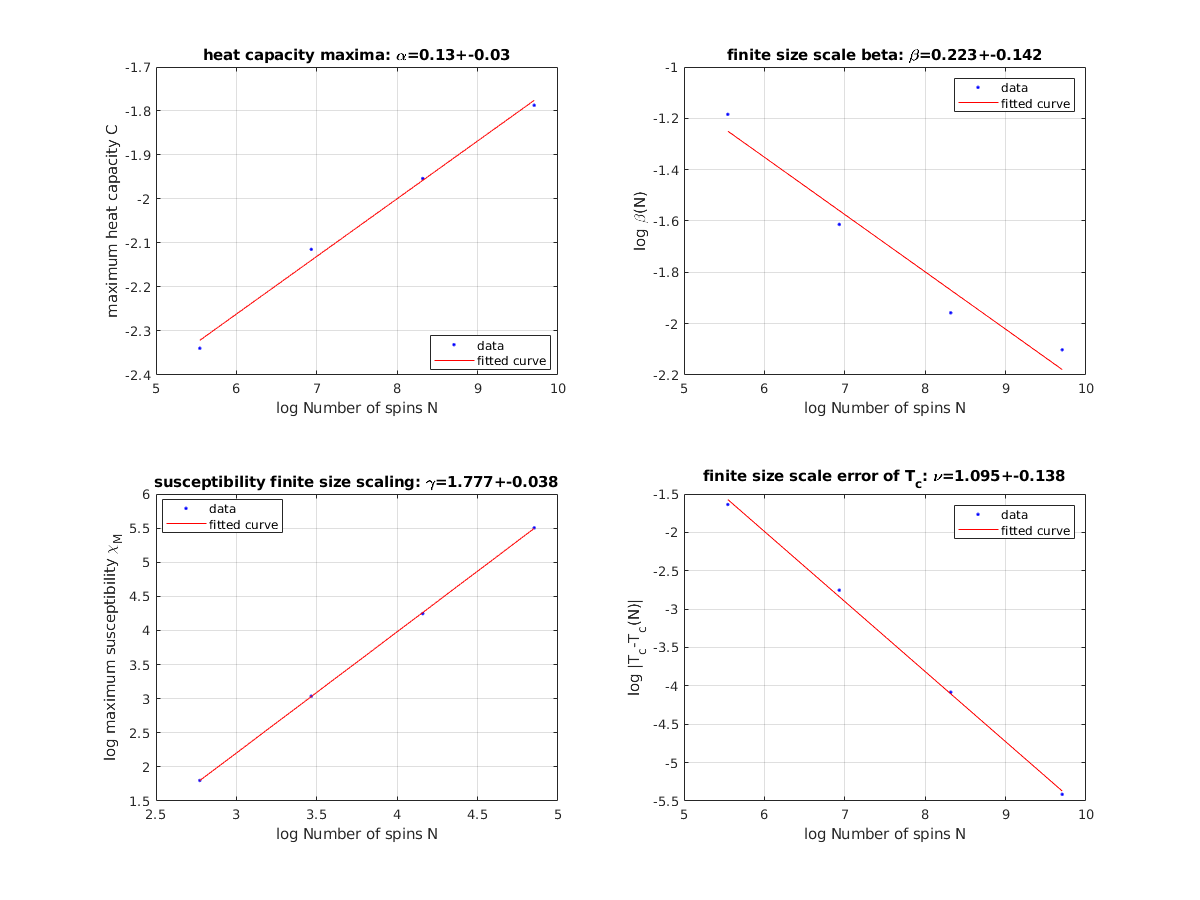


grid on
box on
xlabel("log Number of spins N")
ylabel("log maximum susceptibility \chi_M")
title("susceptibility finite size scaling: \gamma="+ (fitSusceptMax.p1)+"+-"+suscept_p1_err)
legend("Location","best")
saveas(gcf,'./plots/fitExponents.png')

fit exponent

% figure(7)
% clf
% 
% ft = fittype( 'fitHeatCap(T,Tcrit,E0,-gamma)', 'independent', 'T');
% opts = fitoptions( 'Method', 'NonlinearLeastSquares' );
% opts.Display = 'Off';
% opts.Lower = [0.001 2.2 0];
% opts.StartPoint = [0.1 2.269 0.25];
% opts.Upper = [Inf 2.3 2];
% %opts.Weights = 1./suscept_err(:,end).^2;
% 
% % Fit model to data.
% [t_cleaned,y_cleaned]=prepareCurveData(T_vals(:,end), suscept(:,end));
% x=[2:0.002:3 ]';
% [t_cleaned,ia]=unique(t_cleaned);
% y=interp1(t_cleaned,y_cleaned(ia),x,"makima");
% 
% 
% [fitSusc_exponent, gof_susc_exponent] = fit( x,y, ft, opts )
% p=plot( fitSusc_exponent, x,y );
% p(1).MarkerSize=10;
% grid on
% box on
% %set(gca,'YScale','log')
% xlabel("temperature T")
% ylabel("susceptibility \chi")
% ylim([0,1.2*max(suscept(:,end))])
% title("susceptibility N="+N_vals(end))

exponent is:

% fitSusc_exponent.gamma
% suscept_gamma_err=table(diff(confint(fitSusc_exponent))/2).Var1(3)

# Binder Cumulants

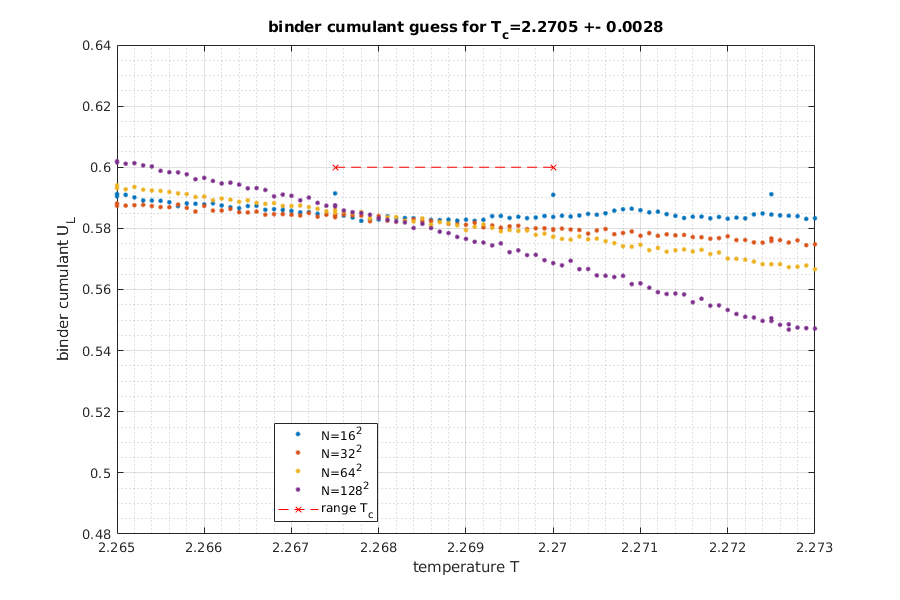

figure('Position', [10 10 900 600])
clf
U_L=(1-mean(data(:,:,2,:).^4,4)./3./mean(data(:,:,2,:).^2,4).^2)';

for i=1:size(data,1)
    plot(T_vals(:,i),U_L(:,i),'.','DisplayName',"N="+N_vals(i)+"^2",'MarkerSize',10);
    hold on
end
box on
grid on
grid minor
legend("Location","best")
title("binder cumulant guess for T_c=2.2705 +- 0.0028")
xlabel("temperature T")
ylabel("binder cumulant U_L")


xlim([2.265 2.273])
%ylim([0.534 0.666])
line([2.2675,2.27],[0.6,0.6],'Color','red','LineStyle','--','Marker','x','DisplayName','range T_c')
saveas(gcf,'./plots/binderCumulant_Tcrit.png')